%clear;

# Tigre Rekonstruktion

## Create Geometry:

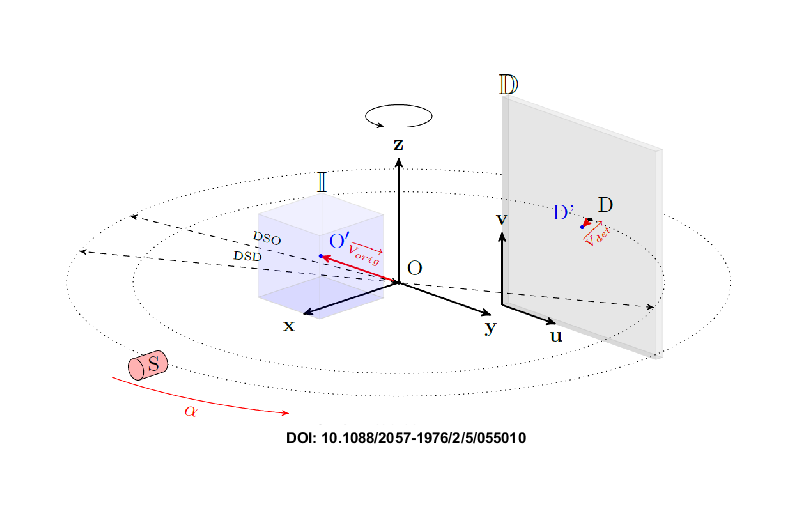

%%  Geometry definition
%
%                  Detector plane, behind
%              |-----------------------------|
%              |                             |
%              |                             |
%              |                             |
%  Centered    |                             |
%    at O      A V    +--------+             |
%              |     /        /|             |
%     A Z      |    /        / |*D           |
%     |        |   +--------+  |             |
%     |        |   |        |  |             |
%     |        |   |     *O |  +             |
%     *--->y   |   |        | /              |
%    /         |   |        |/               |
%   V X        |   +--------+        U       |
%              .--------------------->-------|
%
%            *S
%
%
%% Geometry structure:
%           -nVoxel:        3x1 matrix of number of voxels in the image
%           -sVoxel:        3x1 matrix with the total size in mm of the image
%           -dVoxel:        3x1 matrix with the size of each of the voxels in mm
%           -nDetector:     2x1 matrix of number of voxels in the detector plane
%           -sDetector:     2x1 matrix with the total size in mm of the detector
%           -dDetector:     2x1 matrix with the size of each of the pixels in the detector in mm
%           -DSD:           1x1 scalar value. Distance Source Detector, in mm
%           -DSO:           1x1 scalar value. Distance Source Origin.
%           -offOrigin:     3x1 matrix with the offset in mm of the centre of the image from the origin.
%           -offDetector:   2x1 matrix with the offset in mm of the centre
%           of the detector from the x axis

% Shows Geometry diagram
showGeoCBCTDiagram();

### Geometry for Z-position 200 und %170

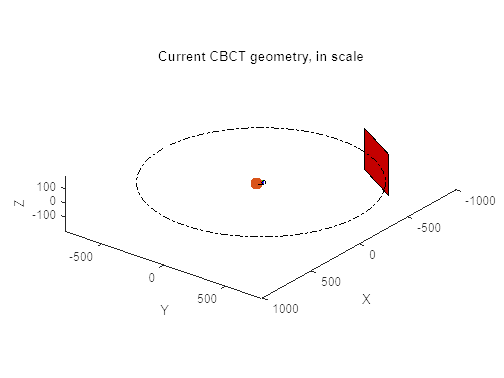

zPos = 200;
switch zPos
    case 200
        % VARIABLE                                   DESCRIPTION                    UNITS
        %-------------------------------------------------------------------------------------
        % Distances
        geo.DSD = 824.34;                           % Distance Source Detector      (mm)
        geo.DSO = 30.38;                            % Distance Source Origin        (mm)
        % Image parameters
        geo.dVoxel=[0.00468;0.00468;0.00468].*2;                                                   
        % Optional Parameters                                            
        geo.COR=15.520089574216115;                 % y direction displacement for 
                                                    % centre of rotation
                                                    % correction                   (mm)
                                                    % This can also be defined per
                                                    % angle            
    case 170
        % Distances
        geo.DSD = 854.34;
        geo.DSO = 60.38;
        % Image parameters
        geo.dVoxel=[0.008976;0.008976;0.008976];
        % Optional Parameters
        geo.COR=8.79141306533552;
end

% Detector parameters
geo.nDetector=[3198;2302]./2;					% number of pixels              (px)
geo.dDetector=[0.127; 0.127].*2; 					% size of each pixel            (mm)
geo.sDetector=geo.nDetector.*geo.dDetector; % total size of the detector    (mm)

% Image parameters
geo.nVoxel= [3198;3198;2302]./2;                % number of voxels              (vx)
geo.sVoxel=geo.dVoxel.*geo.nVoxel;
%geo.sVoxel=[256;256;256];                   % total size of the image       (mm)
%geo.dVoxel=geo.sVoxel./geo.nVoxel;          % size of each voxel            (mm)

% Offsets
geo.offOrigin =[0;0;0];                     % Offset of image from origin   (mm)              
geo.offDetector=[0; 0];                     % Offset of Detector            (mm)  

                                            % These two can be also defined
                                            % per angle

% Auxiliary 
geo.accuracy=0.5;                           % Variable to define accuracy of
                                            % 'interpolated' projection
                                            % It defines the amoutn of
                                            % samples per voxel.
                                            % Recommended <=0.5             (vx/sample)

% Optional Parameters
    % There is no need to define these unless you actually need them in your
    % reconstruction
    
    %geo.rotDetector=[0;0;0];                    % Rotation of the detector, by 
                                                    % X,Y and Z axis respectively. (rad)
                                                    % This can also be defined per
                                                    % angle
%Type
geo.mode='cone';                            % Or 'parallel'. Geometry type.  

%% Alternatively, you can generate default geometries as:

%geoCone=defaultGeometry();
%geoCone=defaultGeometry('mode','cone');
%geoCone=defaultGeometry('nVoxel',[64;64;128]);
%geoCone=defaultGeometry('nDetector',[512;128]);

%% Plot the geometry
                                            
plotgeometry(geo,-pi/6);

## Set up angles and load projections:

angles=linspace(0,2*pi,720);
filename = "DA_JW_7-1__%04d"; % '%04d' bewirkt das in sprintf die Zahl mit Nullen auf 4 Stellen aufgefüllt wird% prealocate

### Set up workers/pool

parpool();

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


### Preallocate

numFiles = length(angles);
proj = zeros(geo.nDetector(2),geo.nDetector(1),numFiles,'single','codistributed');
proj = gather(proj);
disp("preallocation done")

preallocation done


### Load Images

anglesFull=0:3:1440;
parfor j=1:numFiles
    proj(:,:,j)=single(imresize(imread(sprintf(filename,j-1),"tif"),1/2)); %anglesFull(j)
end
beep
disp("done loading images")

done loading images


### Shut down pool

delete(gcp('nocreate'));

## Validate and Invert

%plotProj(proj,angles)
% you need to make sure that:
%     1) white=metal/bone/high density and black=air.
%         If this is not the case
proj=-log(proj/(max(proj(:))+1)); % Beer-Lanbert law
beep
disp("inversion done")

inversion done


%     2) rotation happens left-right instead of top-bottom.
%        If its top bottom:
%proj=permute(proj,[2,1,3]);

%plotProj(proj,angles)

## Reconstruct

imgFDK=FDK(proj,geo,angles); %,'parker',0);

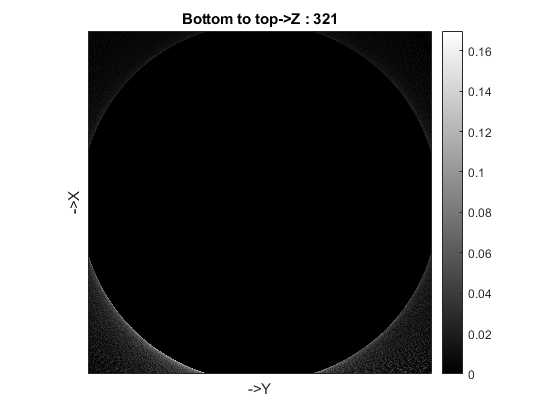

beep
%max(imgFDK(:))
%min(imgFDK(:))
plotImg(imgFDK,'dim','z');  

%niter=20;
%imgOSSART=OS_SART(proj,geo,angles,niter);
%beep
%disp("reconstruction done")

%max(imgOSSART(:))
%min(imgOSSART(:))
%plotImg(imgOSSART,'dim','Z');
% If this does not look good, possible things to check:
% - Are the angles in the right direction? maybe they need to be inverted. 
% - Is your geometry properly defined? mistake on geometry will be
%   detrimental to image quality
% - if microCT: halos around the features? COR correction needed. 

